# Переопределенные системы

### Метод МНК

A = rand(3,2); y = rand(3,1);
x1 = A\y
x2 = (A'*A)^-1*A'*y
eps = x1 - x2

### Элемент наилучшего приближения

Символьное решение

syms x a1 a2
b1 = int(a1+a2*x,0,2*pi)/2/pi
b2 = int((a1+a2*x)*cos(x),0,2*pi)/int(cos(x)^2,0,2*pi)
b3 = int((a1+a2*x)*sin(x),0,2*pi)/int(sin(x)^2,0,2*pi)


x = linspace(0,2*pi);
a1 = 1; a2 = -2;
X = a1+a2*x;
Y = a1+pi*a2-2*a2*sin(x);
plot(x,[X;Y],'LineWidth',2)
xlim([0,2*pi])
grid on
hold off

Численное решение

n = 14;
a = integral(@(x) a1+a2*x,0,2*pi)/2/pi;
Y = a;
for i = 1:n
    ai = integral(@(x) (a1+a2*x).*sin(x*i),0,2*pi)/integral(@(x) sin(x*i).^2,0,2*pi);
     bi = integral(@(x) (a1+a2*x).*cos(x*i),0,2*pi)/integral(@(x) cos(x*i).^2,0,2*pi);
     Y = Y+ai*sin(x*i) + bi*cos(x*i);
end

figure
plot(x,X,'LineWidth',2)
grid on
hold on
xlim([0, 2*pi])
plot(x,Y,'LineWidth',2)

### Элемент наилучшего приближения на сетке

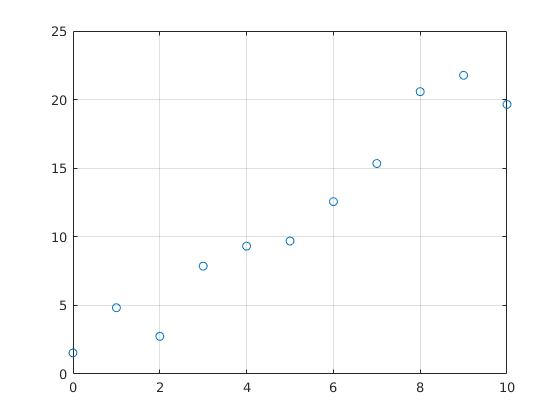

rng(0)
x = linspace(0,10,11);
f = 2*x + 1 + randn(size(x));
figure
plot(x,f,'o')
grid on

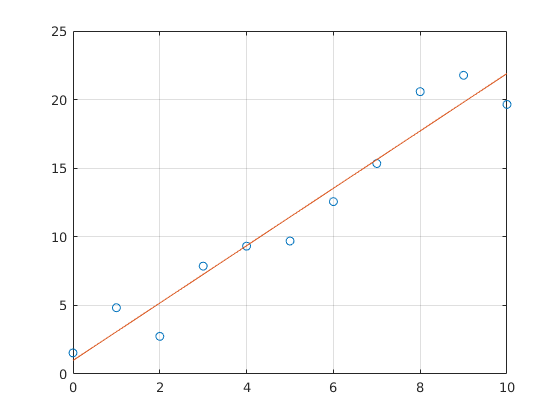


A = [sum(x.^2) sum(x); sum(x) numel(x)];
y = [sum(x.*f); sum(f)];

k = A^-1*y;
a = k(1); b = k(2);

y = a*x+b;
hold on
plot(x,y)


A1 = [x', ones(size(x'))];
k1 = A1\f';
a1 = k1(1); a2 = k1(2);
y1 = k(1)*x + k(2);

err = sum((y-y1).^2)

err = 0